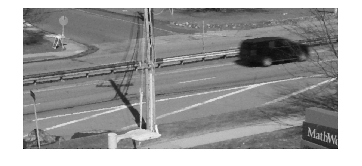

gr = img185;
gr(:,:,1) = medfilt2(gr(:,:,1), [5 5]);
gr(:,:,2) = medfilt2(gr(:,:,2), [5 5]);
gr(:,:,3) = medfilt2(gr(:,:,3), [5 5]);
gr = rgb2gray(gr);
imshow(gr)

v = VideoReader("RoadTraffic.mp4");
vOut = VideoWriter("RoadTraffic-rmNoise.mp4", "MPEG-4");
vOut.FrameRate = v.FrameRate;
open(vOut);

for i = 1:v.NumFrames
    
    img = enhanceImage(read(v, i));
    writeVideo(vOut, img);

end
close(vOut);

dif = abs(im2double(img152) - im2double(img_back));

dif = im2gray(dif) > 0.08;
dif = imopen(dif, strel('disk', 3, 0));
dif = imclose(dif, strel('disk', 10, 0));
dif = imclose(dif, strel('line', 44, 180));
dif = imfill(dif, 'holes');
%dif = uint8(dif) * 255;

t1 = im2gray(dif);

Error using im2gray
Invalid argument at position 1. Value must be numeric.

t1 = t1 > 0;
sum(t1(:))
imshow(dif)

v = VideoReader("RoadTraffic-rmNoise.mp4");
vOut = VideoWriter("RoadTraffic-segment.mp4", "MPEG-4");

vOut.FrameRate = v.FrameRate;
open(vOut);

for i = 1:v.NumFrames
    
    img = read(v, i);

    dif = abs(im2double(img) - im2double(img_back));

    dif = im2gray(dif) > 0.08;
    dif = imopen(dif, strel('disk', 3, 0));
    dif = imclose(dif, strel('disk', 10, 0));
    dif = imclose(dif, strel('line', 44, 180));
    dif = imfill(dif, 'holes');
    dif = uint8(dif) * 255;

    writeVideo(vOut, dif);

end
close(vOut);

props = regionprops(dif, 'Area');
NumberRegions = height(props);
MeanRegionSize = mean([props.Area]);
TotalRegionSize = sum([props.Area]);

NumberRegions

NumberRegions = 3

MeanRegionSize

MeanRegionSize = 2.3084e+04

TotalRegionSize

TotalRegionSize = 69251

V = VideoReader("RoadTraffic-segment.mp4");
V.CurrentTime = 0;

T = table('Size', [V.NumFrames 4], ...
    'VariableTypes', {'uint16', 'uint16', 'uint16', 'uint16'}, ...
    'VariableNames', {'Frame', 'NumberRegions', ...
    'MeanRegionSize', 'TotalRegionSize'});

for i = 1:V.NumFrames

    img = im2gray(readFrame(V));

    props = regionprops(img > 0, 'Area');
    props = props([props.Area] > 500);
    NumberRegions = height(props);
    MeanRegionSize = mean([props.Area]);
    TotalRegionSize = sum([props.Area]);

    T(i,:) = {i, NumberRegions, MeanRegionSize, TotalRegionSize};

end

T

T = 240×4 table
    Frame    NumberRegions    MeanRegionSize    TotalRegionSize
    _____    _____________    ______________    _______________

      1            0                  0                  0     
      2            0                  0                  0     
      3            0                  0                  0     
      4            0                  0                  0     
      5            0                  0                  0     
      6            2               5619              11237     
      7            2              14878              29756     
      8            2              20643              41286     
      9            2              19202              38403     
     10            2              19292              38583     
     11            2              18648              37295     
     12        

sum(T.NumberRegions > 0)

ans = 151

mode(T.NumberRegions)

ans = uint16
1

median(T.MeanRegionSize(T.MeanRegionSize > 0))

ans = uint16
17644

V = VideoReader("RoadTraffic-segment.mp4");
V.CurrentTime = 0;
vOut = VideoWriter("RoadTraffic-box.mp4", "MPEG-4");
vOut.FrameRate = v.FrameRate;
open(vOut);

for i = 1:V.NumFrames

    img = readFrame(V);
    img_g = im2gray(img);

    props = regionprops(img_g > 0, 'Area', 'BoundingBox');
    props = props([props.Area] > 500);
    NumberRegions = height(props);
    
    if NumberRegions == 1
        tBoxed = insertShape(img, "rectangle", props.BoundingBox, "LineWidth", 3, "Color", "yellow");
        writeVideo(vOut, tBoxed);
    else
        writeVideo(vOut, img);
    end

end
close(vOut);